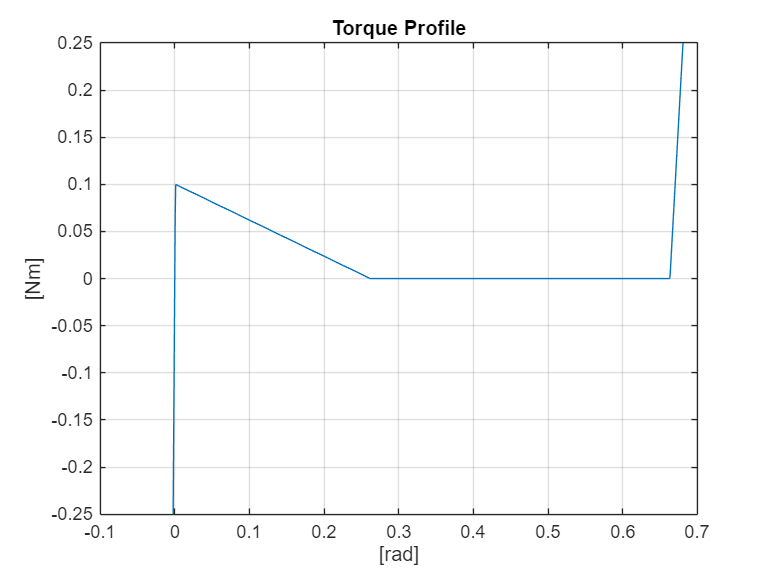

clc
clear
close all

% --- SPRING PARAMS ---
d0 = 27.5e-3;
k = 1.75e3;
d_max = 40e-3;
SF = 1.5;
% ---------------------

% % TORQUE PROFILE POINTS (rad)
% P = [0    0
%      0.01 0.2
%      0.15  0.0
%      0.8  0.0
%      0.9  0.4];

% TORQUE PROFILE POINTS (deg)
P = [-0.25   -0.25
     0.1 0.1
     30  0.0
     76  0.0
     78  0.25];
P(:,1) = P(:,1)/2/180*pi;


% ---------------------

x = linspace(min(P(:,1)), max(P(:,1)),1e3);
t = interp1(P(:,1),P(:,2),x);
r0 = d_max/(2);%*SF);

figure
plot(x,t)
title('Torque Profile')
xlabel('[rad]')
ylabel('[Nm]')
grid on

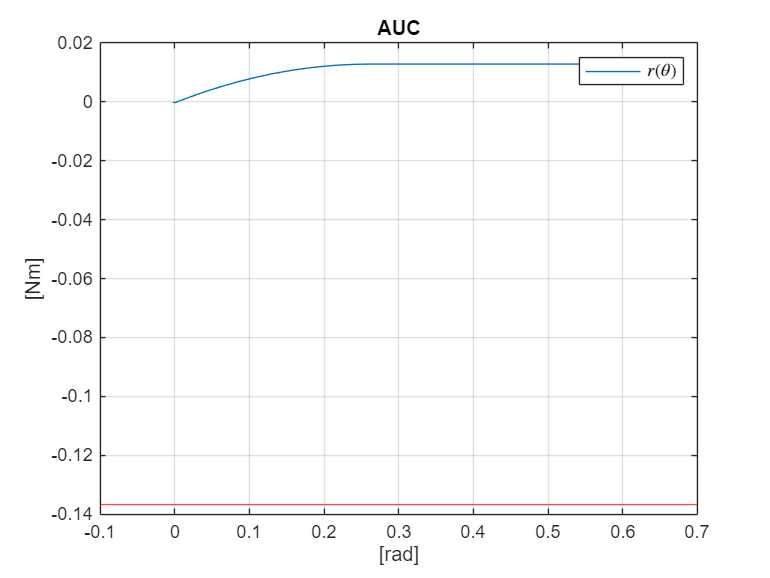

T = cumtrapz(x,t);

figure
plot(x,T)
title('AUC')
xlabel('[rad]')
ylabel('[Nm]')
grid on
hold on
Emin = -k*(2*r0-d0)^2/2;
yline(Emin,'r')
legend({'$r(\theta)$'},"Interpreter","latex","FontSize",10)

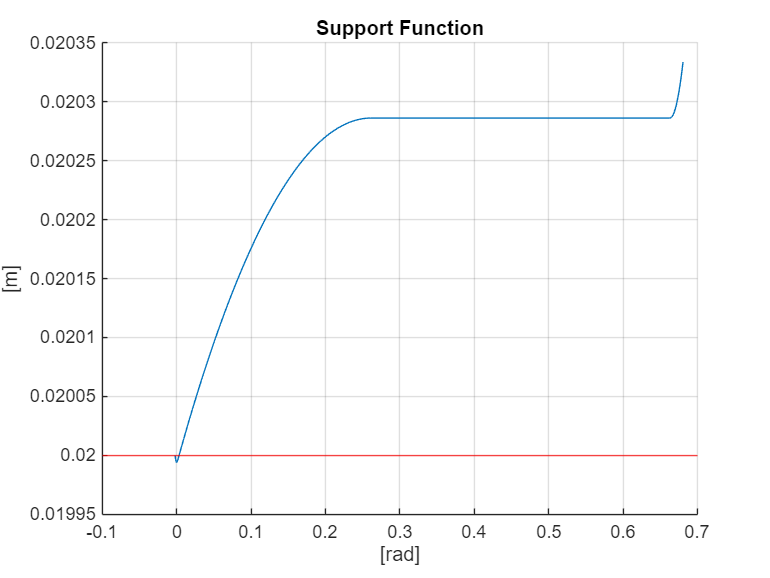

r = 0.5*(d0 + sqrt((2*r0 - d0)^2 + 2*T/k));

dx = x(2) - x(1);
dr  = gradient(r, dx); dr(1) = 0;
ddr = gradient(dr, dx);

figure
hold on
plot(x,r)
yline(d_max/2,'r')
title('Support Function')
xlabel('[rad]')
ylabel('[m]')
grid on

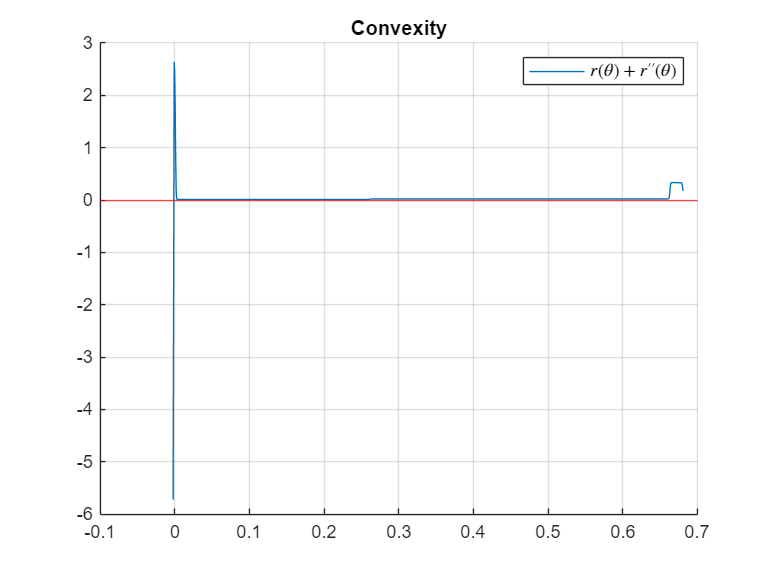


figure
hold on
plot(x,r + ddr)
yline(0,'r')
title('Convexity')
grid on


legend({'$r(\theta) + r''''(\theta)$'},"Interpreter","latex","FontSize",10)

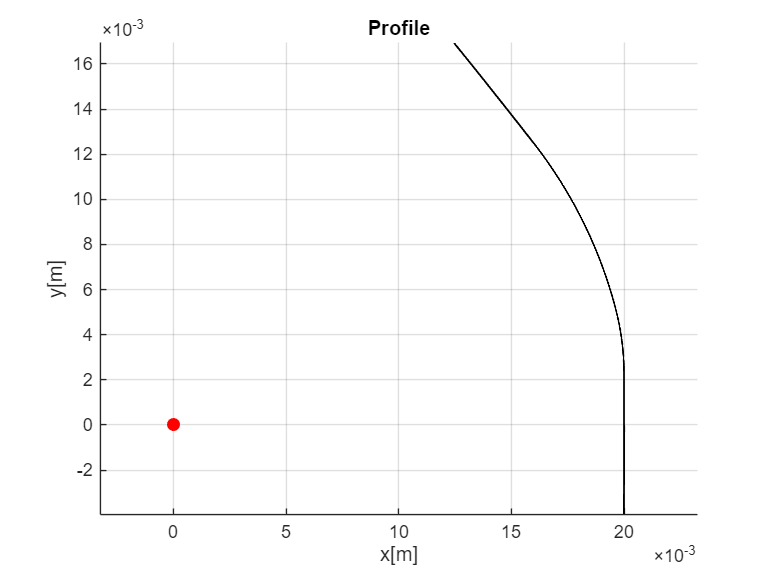

xc = r.*cos(x) - dr.*sin(x);
yc = r.*sin(x) + dr.*cos(x);

figure
hold on
plot(xc,yc,'k','LineWidth',1)
% plot(xc,-yc,'k','LineWidth',1)
scatter(0,0,50,'filled','or')
title('Profile')
xlabel('x[m]')
ylabel('y[m]')
axis equal
grid on